# Data localization

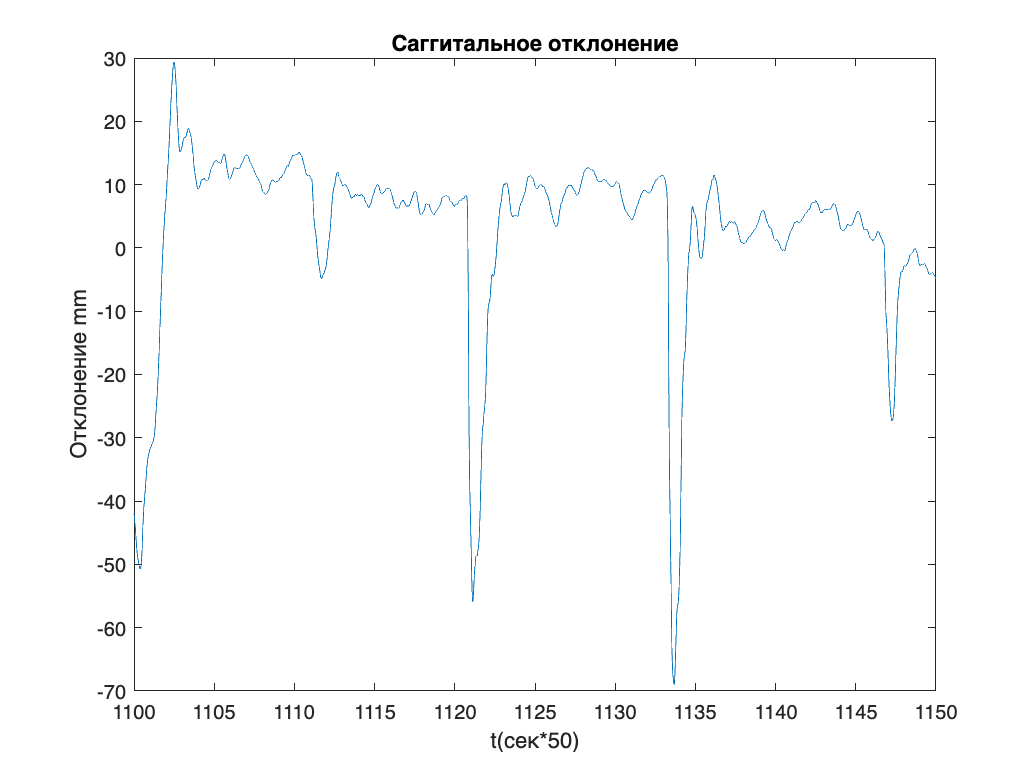

fur=@furiermy;

ymy1=load('R1_my');
Y_my=ymy1(:,2);


plot(0.02:0.02:length(Y_my)/50,Y_my');
title("Саггитальное отклонение");xlabel('t(сек*50)');ylabel("Отклонение mm")
xlim([1100 1150]);

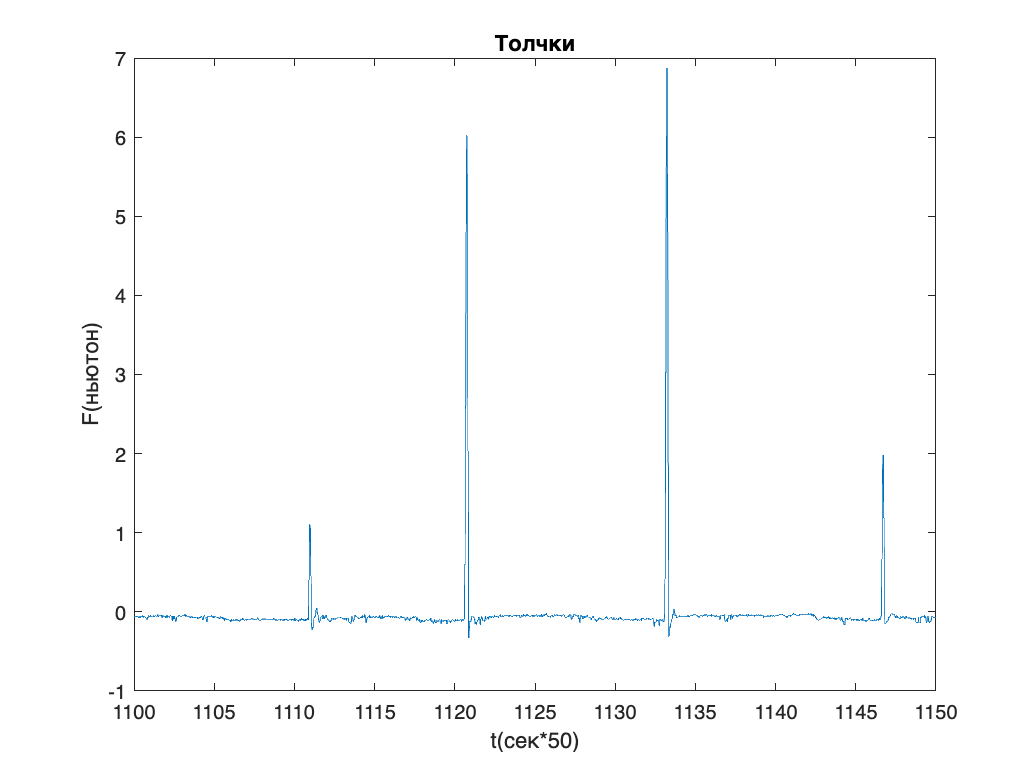



plot(0.02:0.02:length(Y_my)/50,ymy1(:,4));
title("Толчки");xlabel('t(сек*50)');ylabel("F(ньютон)")
xlim([1100 1150]);

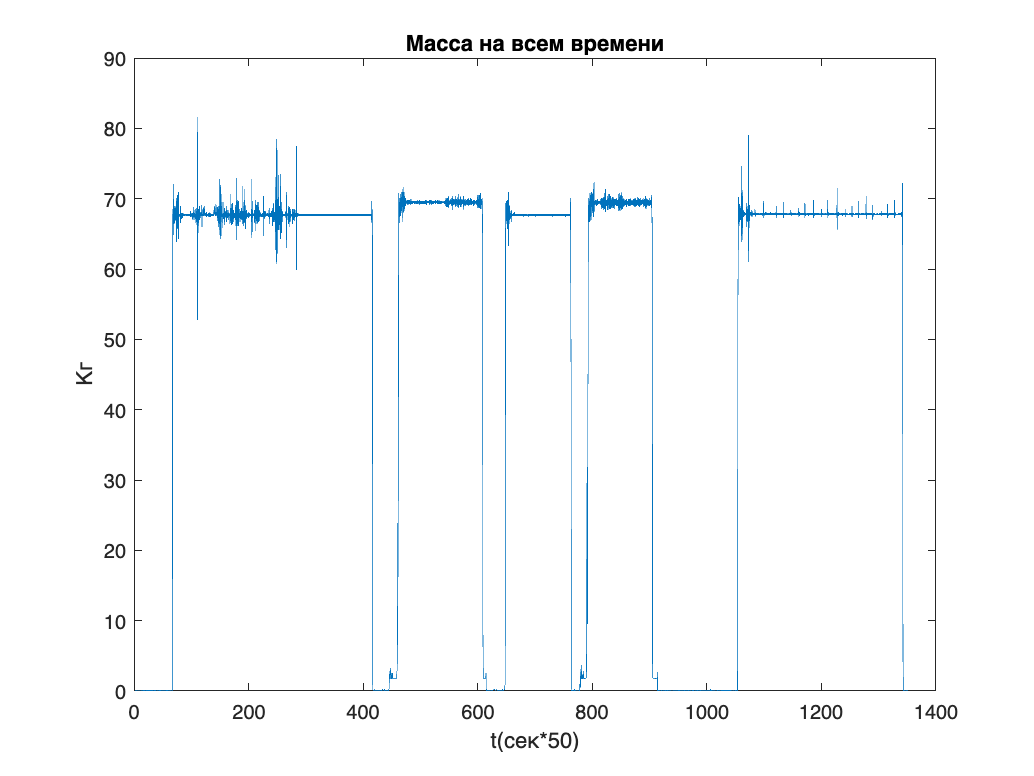


plot(0.02:0.02:length(Y_my)/50,ymy1(:,3));
title("Масса на всем времени");xlabel('t(сек*50)');ylabel("Кг")

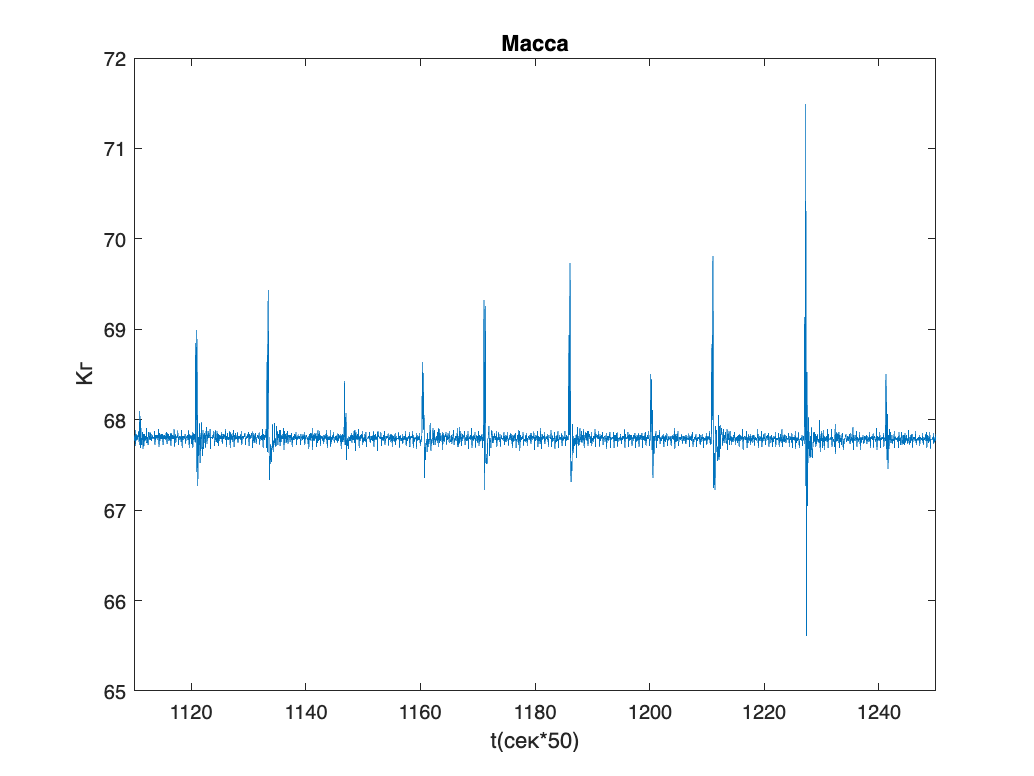


plot(0.02:0.02:length(Y_my)/50,ymy1(:,3));
title("Масса");xlabel('t(сек*50)');ylabel("Кг")
xlim([1110 1250]);

# Mean mass

massWindow=ymy1(:,3);
m=mean(massWindow(1110*50:1250*50))

m = 67.8015

# Apply algo for real data

l=0.88;
l1=1.3

l1 = 1.3000

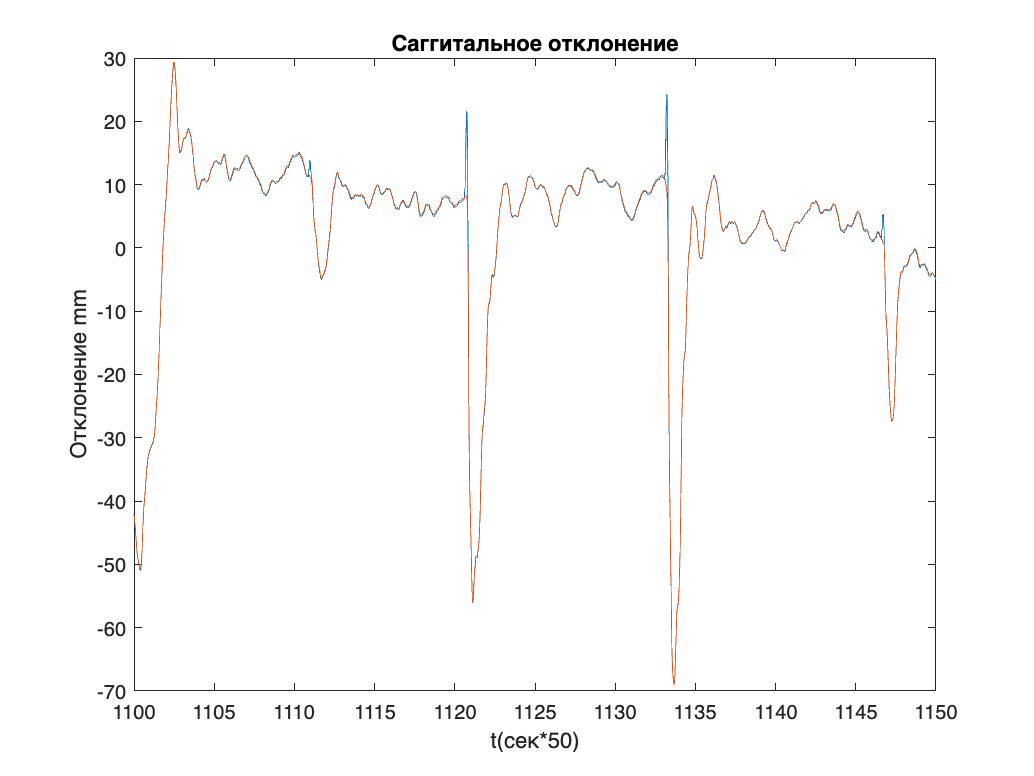

h=l*2;
hp = 0.07 * (1 + h);
g=9.81;
J = m * l^2 / 3 + hp * m * l;
mgh=m*g*h;
ticks=512;
t=1:512;
F=ymy1(:,4);
fur2=@COPMfftfilt;

yCorrected=Y_my+1000*F*(l1+hp)/(m*g);
plot(0.02:0.02:length(Y_my)/50,yCorrected,0.02:0.02:length(Y_my)/50,Y_my');
title("Саггитальное отклонение");xlabel('t(сек*50)');ylabel("Отклонение mm")
xlim([1100 1150]);


yCorrected=yCorrected(1116*50:1116*50+511);
yOrig=Y_my(1116*50:1116*50+511);

% ycorrected=ybase2-Fnum*(l+hp)/(m*g);
% ycorrected=ybase2-Fnum*(l+hp)/(m*g);
afterfur2=COPMfftfilt(yCorrected,ticks,J,mgh);

# Plot after FFT filtering

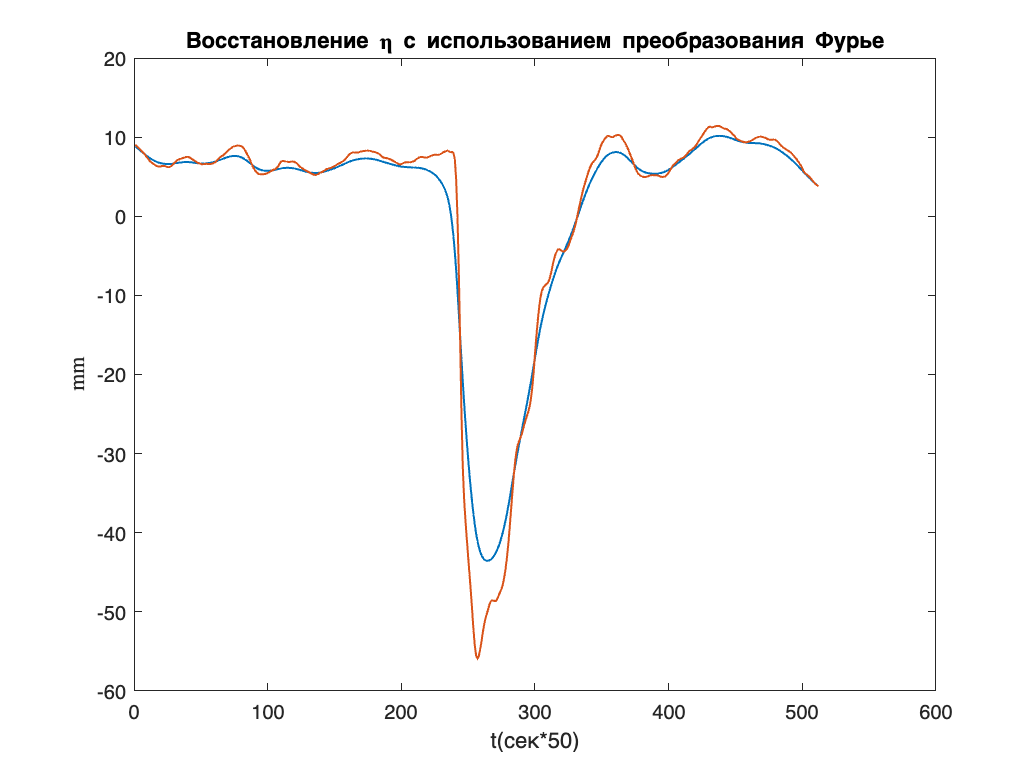

plot(t,afterfur2,t,yOrig,'LineWidth',1);
title("Восстановление \eta с использованием преобразования Фурье")
xlabel("t(сек*50)");ylabel('mm','Interpreter','latex')

% legend('$\eta$','t','Interpreter','latex')

# Apply algo double filtering for real data

doubleFilt=@COPMdoublefilt;
afterDoubleFilter=doubleFilt(yCorrected,J,m,g,l);

# Plot after double filtering

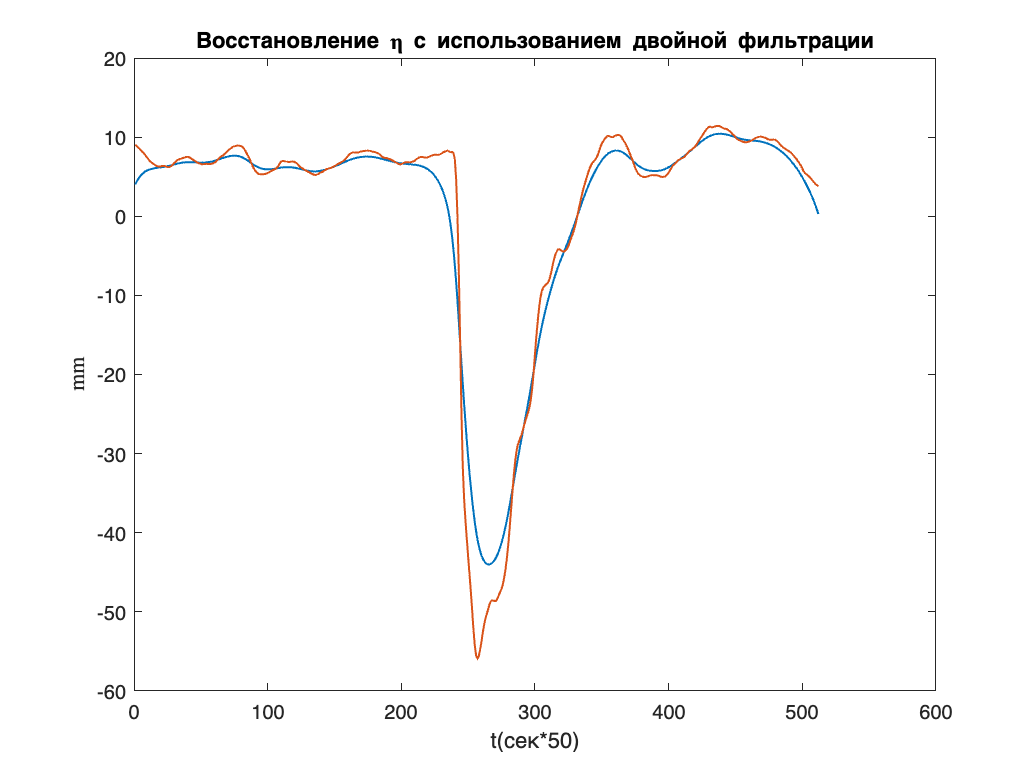

plot(t,afterDoubleFilter,t,yOrig,'LineWidth',1);
title("Восстановление \eta с использованием двойной фильтрации")
xlabel("t(сек*50)");ylabel('mm','Interpreter','latex')

% legend('$\eta$','t','Interpreter','latex')

# Find average M values by eyes

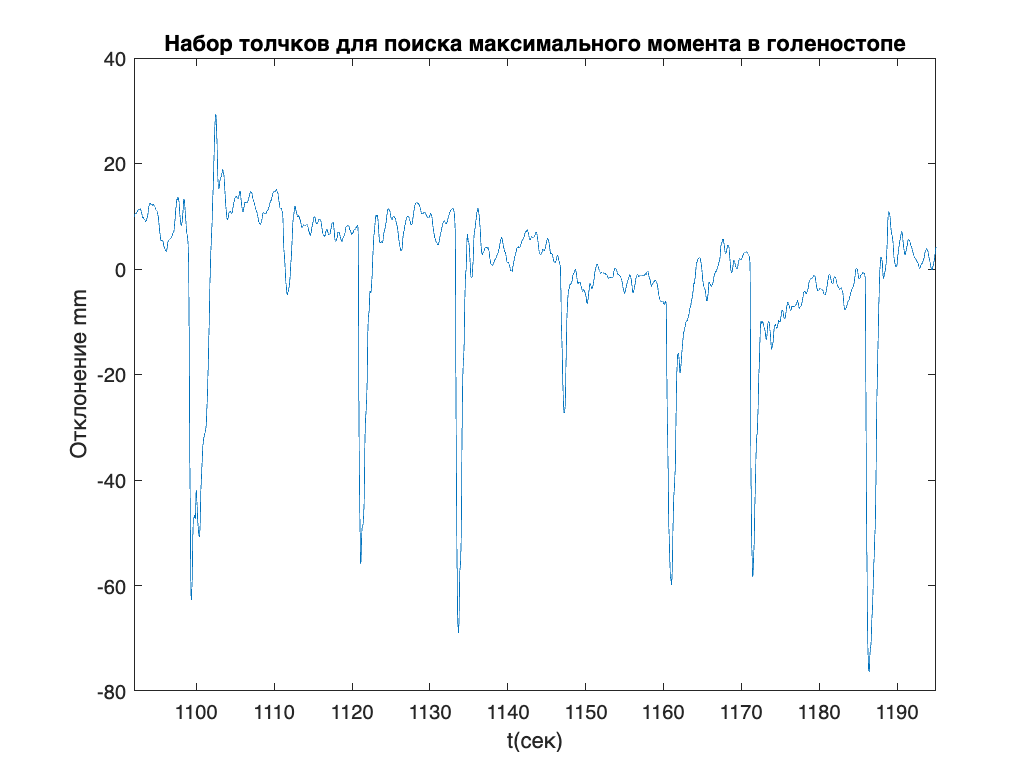

plot(0.02:0.02:length(Y_my)/50,Y_my');
title("Набор толчков для поиска максимального момента в голеностопе");xlabel('t(сек)');ylabel("Отклонение mm")
xlim([1092 1195]);

% ax = gca;
% chart = ax.Children(1);
% datatip(chart,1122,-9.523);
% datatip(chart,1134,-16.25);
% datatip(chart,1134,-54.84);
% datatip(chart,1121,-47.84);

# Calcualte median values for mom and momDerivatives

% points=[1121.44 1122.08 -9.52344-(-47.8438);
%     1101.24 1102.38 26.53-(-30.04); 
%     1186.68 1187.74 -2.39-(-70.0859);
%     1278.64 1279.48 -7.67-(-75.50);
%     1133.98 1134.58 -1.14-(-53.5959);
%     ]
% on the first part of pushes
points=[1120.78 1121.08 7.18+54.32;
    1098.96 1099.32 4.03+60.7; 
    1185.9 1186.2 -1.52-(-66.7);
    1277.78 1278.04 -5.98-(-73.3);
    1133.26 1133.58 5.86+66.71;
    ]

points = 1.0e+03 *

    1.1208    1.1211    0.0615
    1.0990    1.0993    0.0647
    1.1859    1.1862    0.0652
    1.2778    1.2780    0.0673
    1.1333    1.1336    0.0726


mom=m*g*points(:,3)/1000;
momDeriv=mom./abs(points(:,1)-points(:,2));

meanMom=mean(mom)

meanMom = 44.0717

meanMomDerivative=mean(momDeriv)

meanMomDerivative = 144.7032

# Compare pushes and Y_coord

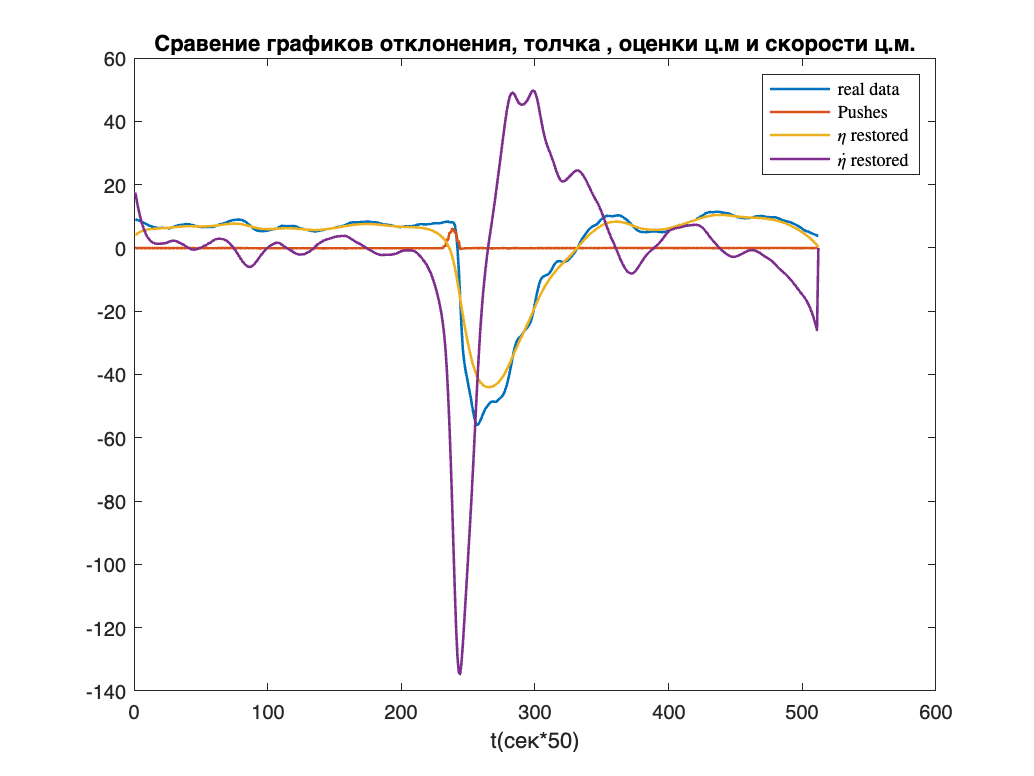

pushesData=ymy1(:,4);
pushesData;
plot(1:length(yOrig),yOrig,1:length(yOrig),pushesData(1116*50:1116*50+511),1:length(yOrig),afterDoubleFilter,1:length(yOrig),[diff(afterDoubleFilter)'/0.02 0],'LineWidth',1.3);
% plot(1:length(yCorrected),yCorrected)
title("Сравение графиков отклонения, толчка , оценки ц.м и скорости ц.м.");xlabel('t(сек*50)');
legend('real data','Pushes','$\eta$ restored','$\dot{\eta}$ restored','Interpreter','latex')

% xlim([1120 1135]);

# Find \eta and derivative \eta

etaDerivative=diff(afterDoubleFilter)/0.02;
% correct our data for 6-10 mm ofsset
offset=mean([afterDoubleFilter(380:450);afterDoubleFilter(20:200)]);
afterDoubleFilter=afterDoubleFilter-offset;
initialEtaDeriv=etaDerivative(245);
initialEta=afterDoubleFilter(245);

theta0=rad2deg(-initialEta/1000/l);
omega0=rad2deg(-initialEtaDeriv/1000/l);

theta0=-initialEta/1000/l

theta0 = 0.0292

omega0=-initialEtaDeriv/1000/l

omega0 = 0.1490

# Find some variables for control problem 

tast=sqrt(l/(3*g)) %simplfy eq

tast = 0.1729

% u=tast*meanMomDerivative/(m*g*l*theta0)

# Modeling moment with calculated data

syms M(t);

u=2;
tauf=0.484;tau2=0.403;tau1=0.161;
meamMomDerivFake=u*m*g*l*theta0/tast

meamMomDerivFake = 197.9263



firstPoint=-meamMomDerivFake*tau1

firstPoint = -31.8661

secondPoint=firstPoint+meamMomDerivFake*tau2

secondPoint = 47.8982

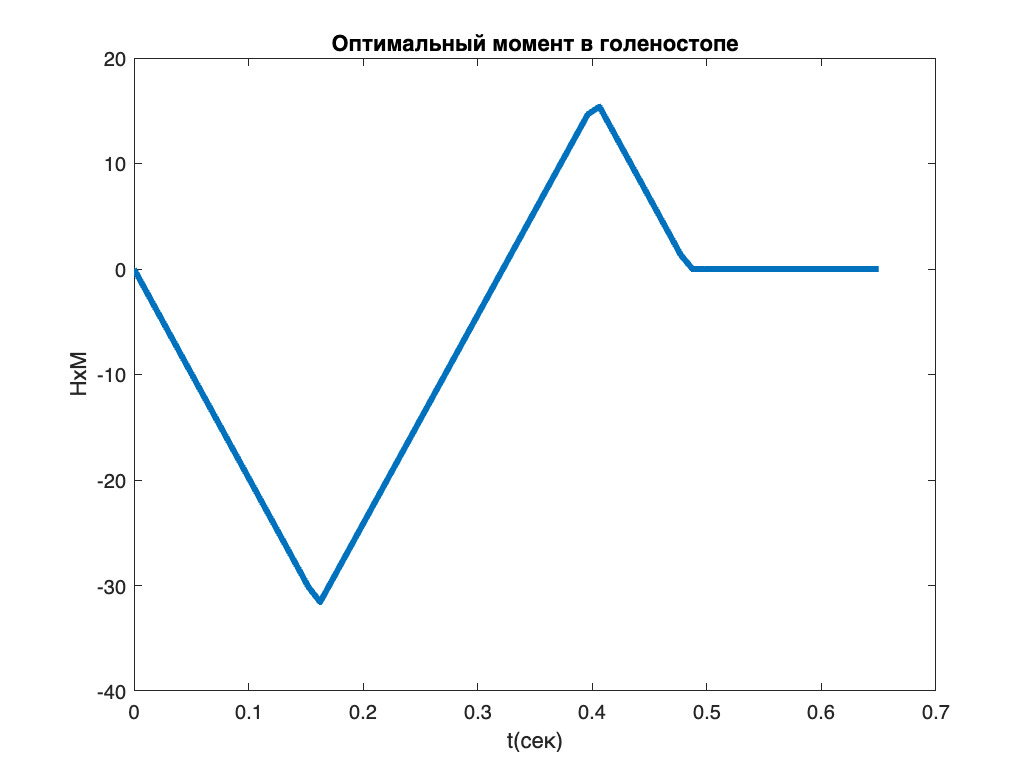

M(t) = piecewise((0 <= t) & (t <= tau1),-meamMomDerivFake*t, ...
    (tau1 < t) & (t <= tau2),2*firstPoint+meamMomDerivFake*t, ...
    (tau2 < t) & (t <= tauf),2*secondPoint-meamMomDerivFake*t,0);

t=linspace(0,0.65,65);


plot(t,double(M(t)),'LineWidth',3);
title("Оптимальный момент в голеностопе");xlabel('t(сек)');ylabel("НхМ")

# Compare trajectory

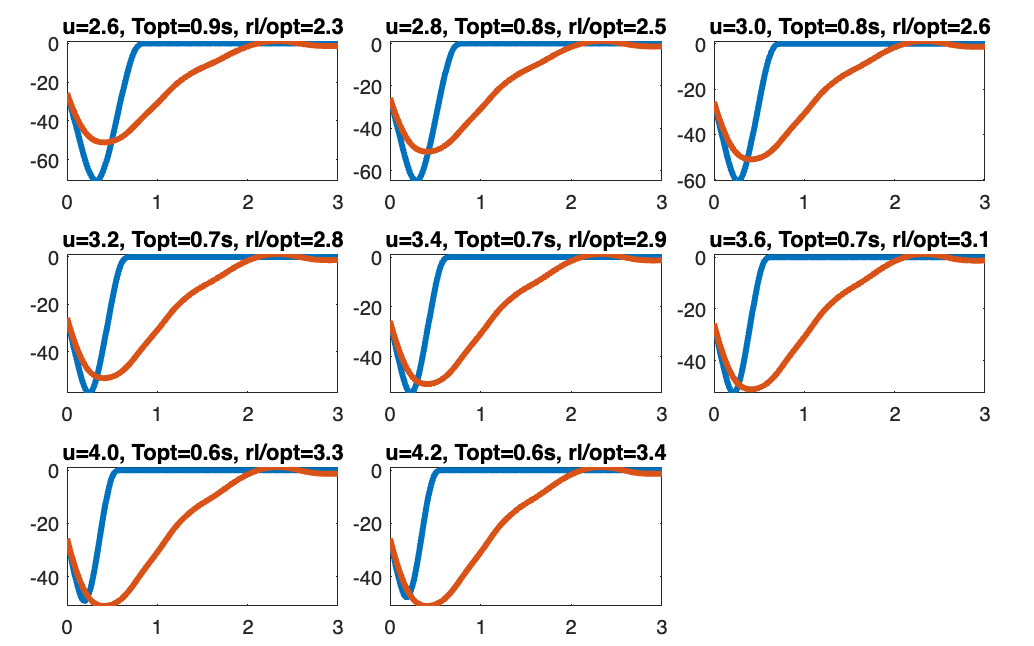

optimalEta=load("file.mat").optEta;
tf=load("file.mat").tf;
tauf=load("file.mat").tauf;
uast=load("file.mat").uast;

t = tiledlayout(3,fix(length(tf)/3));

for ind = 1:length(tf)
    if tf(ind)~=0
        nexttile
        tast=tf(ind)/tauf(ind);
        ticks=round(linspace(2,length(optimalEta(ind,:)),length(optimalEta(ind,:))*tast));
        limit=150;
        realT=2.0;
        plot(linspace(0,limit/50,limit),[optimalEta(ind,ticks) zeros([1 limit-length(ticks)])],linspace(0,limit/50,limit),afterDoubleFilter(245:244+limit),'LineWidth',3);
        title(sprintf('u=%.1f, Topt=%.1fs, rl/opt=%.1f', uast(ind),tf(ind),realT/tf(ind)));
        t.Padding = 'compact';
        t.TileSpacing = 'compact';
%         xlabel("t(сек)");ylabel('$\eta$(mm)','Interpreter','latex')
%         legend('optimal','real','Interpreter','latex')
    else
    end
end


set(gcf, 'Position', get(0, 'Screensize'));
% tast=tf/tauf;
% ticks=round(linspace(2,length(optimalEta),length(optimalEta)*tast));
% 
% limit=150;
% realT=2.0
% plot(linspace(0,limit/50,limit),[optimalEta(ticks) zeros([1 limit-length(ticks)])],linspace(0,limit/50,limit),afterDoubleFilter(245:244+limit),'LineWidth',3);
% title(sprintf('Траектория ц.м. u=%.1f, Treal=2sec, Topt=%.1fsec, real/opt=%.1f', uast,tf,realT/tf));
% xlabel("t(сек)");ylabel('$\eta$(mm)','Interpreter','latex')
% legend('optimal','real','Interpreter','latex')


function xn=COPMfftfilt(sy,N,J,mgh)

nt=(1:N)';
a=(sy(N)-sy(1))/(N-1);
b=(sy(N)-sy(1))/2;
x=sy(1:N)-a*nt-b;
f=(1:N)/N*50*2*pi;
kw=-mgh./(J*f(1:(N/2+1)).^2+mgh);
S=fft(x,N);
Sn=S(1:(N/2+1)).*kw';   
Sn((N/2+2):N)=flipud(conj(Sn(2:(N/2))));
xn=ifft(Sn)-a*nt-b;
xn=-1*xn;
end

function enddata=COPMdoublefilt(y,J,m,g,l)

numerator=1;
denominator=[sqrt((J)/(m*g*l)) 1];
H = tf(numerator,denominator);
Hd = c2d(H,12/512,'foh');

miidledata=filter(cell2mat(Hd.numerator),cell2mat(Hd.denominator),y);


numerator=1;
denominator=[sqrt((J)/(m*g*l)) 1];
H = tf(numerator,denominator);
Hd2 = c2d(H,12/512,'foh');

enddata=flip(filter(cell2mat(Hd2.numerator),cell2mat(Hd2.denominator),flip(miidledata)));
end
